## Incryption

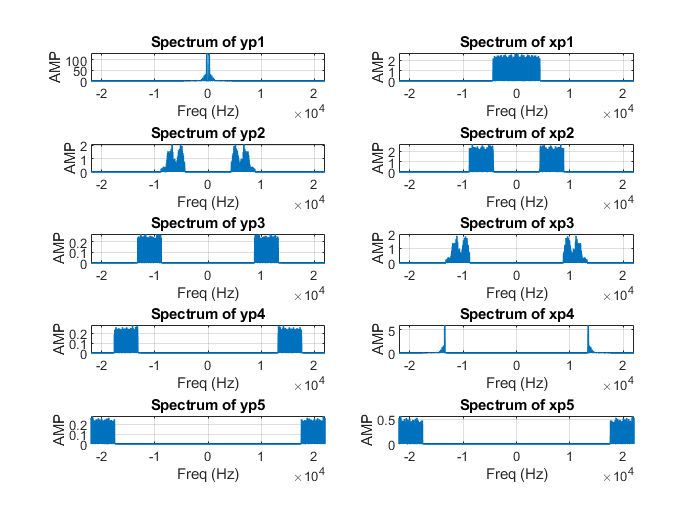


%loading the recorded audio
[y_p, fs_p] = audioread('C:\Users\pc world\Desktop\S&S_FinalProject_14022\recorded.wav');
load('C:\Users\pc world\Desktop\S&S_FinalProject_14022\filters.mat')
player = audioplayer(y_p, fs_p);

% Play the sound
 %play(player)

B = [0 0 0 10 0; 
     0 0 10 0 0;
     0 1 0 0 0;
     0.05 0 0 0 0;
     0 0 0 0 1];

ts_p = 1 / fs_p;
t_p = 0:ts_p:(length(y_p) - 1) * ts_p;

band1_fp = fs_p / 10;
band2_fp = 2 * (fs_p / 10);
band3_fp = 3 * (fs_p / 10);
band4_fp = 4 * (fs_p / 10);

c1 = cos(2 * pi * band1_fp * t_p)';
c2 = cos(2 * pi * band2_fp * t_p)';
c3 = cos(2 * pi * band3_fp * t_p)';
c4 = cos(2 * pi * band4_fp * t_p)';

yp1 = filter(Band1, y_p);
yp2 = filter(Band2, y_p);
yp3 = filter(Band3, y_p);
yp4 = filter(Band4, y_p);
yp5 = filter(Band5, y_p);

Y_P = [yp1, yp2, yp3, yp4, yp5];

xp1 = zeros(length(y_p), 1);
xp2 = zeros(length(y_p), 1);
xp3 = zeros(length(y_p), 1);
xp4 = zeros(length(y_p), 1);
xp5 = zeros(length(y_p), 1);

xp1 = filter(Band1, xp1);
xp2 = filter(Band2, xp2);
xp3 = filter(Band3, xp3);
xp4 = filter(Band4, xp4);
xp5 = filter(Band5, xp5);

X_P = [xp1, xp2, xp3, xp4, xp5];
X_P = Y_P * B';

xp1 = X_P(:,1);
xp2 = X_P(:,2);
xp3 = X_P(:,3);
xp4 = X_P(:,4);
xp5 = X_P(:,5);

xp1 = xp1 .*c3;
xp1 = filter(Band1,2*xp1);
xp2 = xp2 .*c1;
xp2 = filter(Band2,2*xp2);
xp3 = xp3 .*c1;
xp3 = filter(Band3,2*xp3);
xp4 = xp4 .*c3;
xp4 = filter(Band4,2*xp4);
xp5 = filter(Band5,2*xp5);

xp = xp1 + xp2 + xp3 + xp4 + xp5;

player = audioplayer(xp, fs_p);
% play(player)

audiowrite('C:\Users\pc world\Desktop\S&S_FinalProject_14022\recorded_encrypted.wav', xp, fs_p);
figure;
subplot(5, 2, 1); FFT(yp1, fs_p); title('Spectrum of yp1');
subplot(5, 2, 2); FFT(xp1, fs_p); title('Spectrum of xp1');
subplot(5, 2, 3); FFT(yp2, fs_p); title('Spectrum of yp2');
subplot(5, 2, 4); FFT(xp2, fs_p); title('Spectrum of xp2');
subplot(5, 2, 5); FFT(yp3, fs_p); title('Spectrum of yp3');
subplot(5, 2, 6); FFT(xp3, fs_p); title('Spectrum of xp3');
subplot(5, 2, 7); FFT(yp4, fs_p); title('Spectrum of yp4');
subplot(5, 2, 8); FFT(xp4, fs_p); title('Spectrum of xp4');
subplot(5, 2, 9); FFT(yp5, fs_p); title('Spectrum of yp5');
subplot(5, 2, 10); FFT(xp5, fs_p); title('Spectrum of xp5');

## Spectrum of the real audio

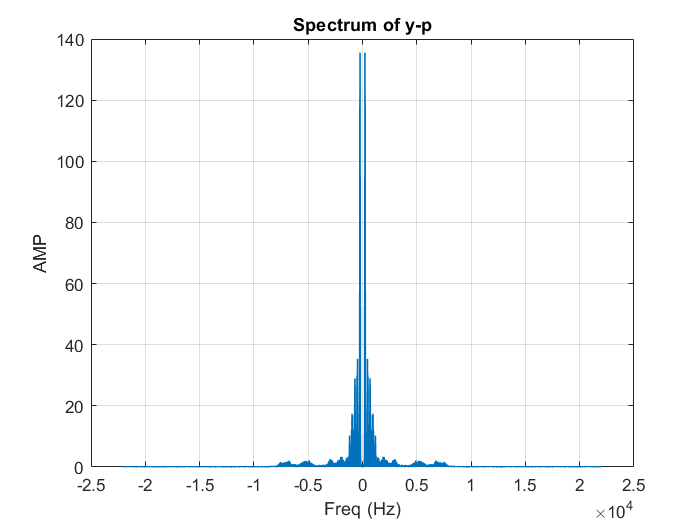


figure;
FFT(y_p, fs_p); title('Spectrum of y-p');

## Spectrum of the encrypted audio

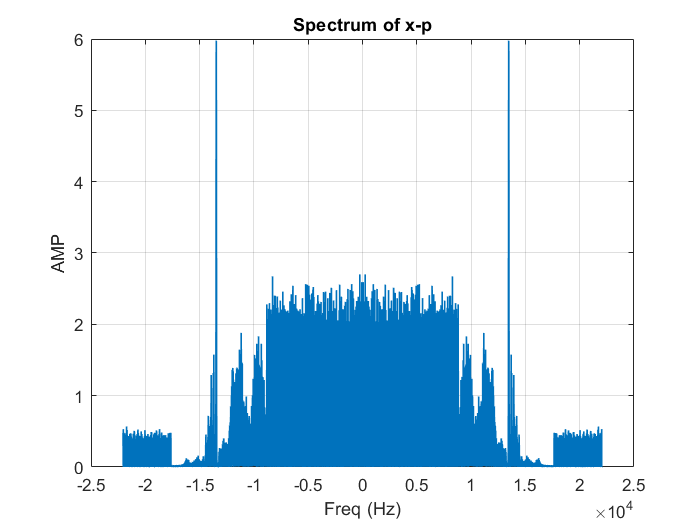


figure;
FFT(xp, fs_p); title('Spectrum of x-p');

## Decryption

[y_z, fs_z] = audioread('C:\Users\pc world\Desktop\S&S_FinalProject_14022\recorded_encrypted.wav');
Binv = inv(B);
disp(Binv)

         0         0         0   20.0000         0
         0         0    1.0000         0         0
         0    0.1000         0         0         0
    0.1000         0         0         0         0
         0         0         0         0    1.0000



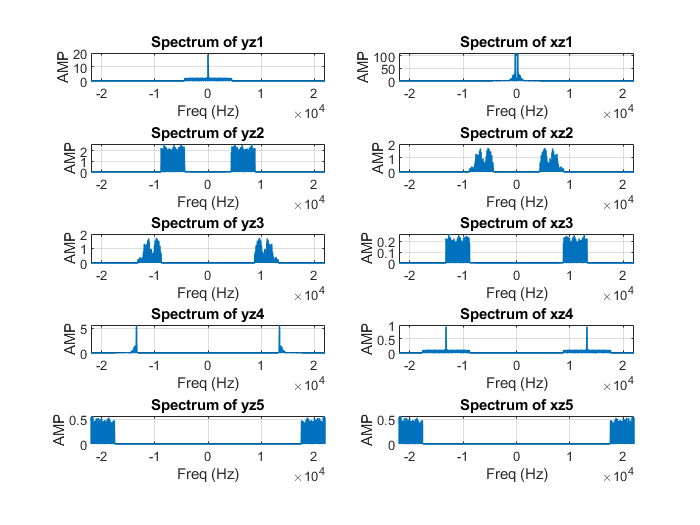


yz1 = filter(Band1, y_z);
yz2 = filter(Band2, y_z);
yz3 = filter(Band3, y_z);
yz4 = filter(Band4, y_z);
yz5 = filter(Band5, y_z);

Y_Z = [yz1, yz2, yz3, yz4, yz5];

xz1 = zeros(length(y_z), 1);
xz2 = zeros(length(y_z), 1);
xz3 = zeros(length(y_z), 1);
xz4 = zeros(length(y_z), 1);
xz5 = zeros(length(y_z), 1);

xz1 = filter(Band1, xz1);
xz2 = filter(Band2, xz2);
xz3 = filter(Band3, xz3);
xz4 = filter(Band4, xz4);
xz5 = filter(Band5, xz5);

X_Z = [xz1, xz2, xz3, xz4, xz5];
X_Z = Y_Z * Binv';

xz1 = X_Z(:,1);
xz2 = X_Z(:,2);
xz3 = X_Z(:,3);
xz4 = X_Z(:,4);
xz5 = X_Z(:,5);
ts_z = 1 / fs_z;
t_z = 0:ts_z:(length(y_z) - 1) * ts_z;

band1_fz = fs_z / 10;
band2_fz = 2 * (fs_z / 10);
band3_fz = 3 * (fs_z / 10);
band4_fz = 4 * (fs_z / 10);

cz1 = cos(2 * pi * band1_fz * t_z)';
cz2 = cos(2 * pi * band2_fz * t_z)';
cz3 = cos(2 * pi * band3_fz * t_z)';
cz4 = cos(2 * pi * band4_fz * t_z)';
xz1 = xz1 .*cz3;
xz1 = filter(Band1,2*xz1);
xz2 = xz2 .*cz1;
xz2 = filter(Band2,2*xz2);
xz3 = xz3 .*cz1;
xz3 = filter(Band3,2*xz3);
xz4 = xz4 .*cz3;
xz5 = filter(Band5,xz5);

figure;
subplot(5, 2, 1); FFT(yz1, fs_z); title('Spectrum of yz1');
subplot(5, 2, 2); FFT(xz1, fs_z); title('Spectrum of xz1');
subplot(5, 2, 3); FFT(yz2, fs_z); title('Spectrum of yz2');
subplot(5, 2, 4); FFT(xz2, fs_z); title('Spectrum of xz2');
subplot(5, 2, 5); FFT(yz3, fs_z); title('Spectrum of yz3');
subplot(5, 2, 6); FFT(xz3, fs_z); title('Spectrum of xz3');
subplot(5, 2, 7); FFT(yz4, fs_z); title('Spectrum of yz4');
subplot(5, 2, 8); FFT(xz4, fs_z); title('Spectrum of xz4');
subplot(5, 2, 9); FFT(yz5, fs_z); title('Spectrum of yz5');
subplot(5, 2, 10); FFT(xz5, fs_z); title('Spectrum of xz5');

xz = xz1 + xz2 + xz3 + xz4 + xz5;
player = audioplayer(xz, fs_z);
% play(player)

audiowrite('C:\Users\pc world\Desktop\S&S_FinalProject_14022\recorded_de_encrypted.wav', xz, fs_z);

## Spectrum of the encrypted oudio

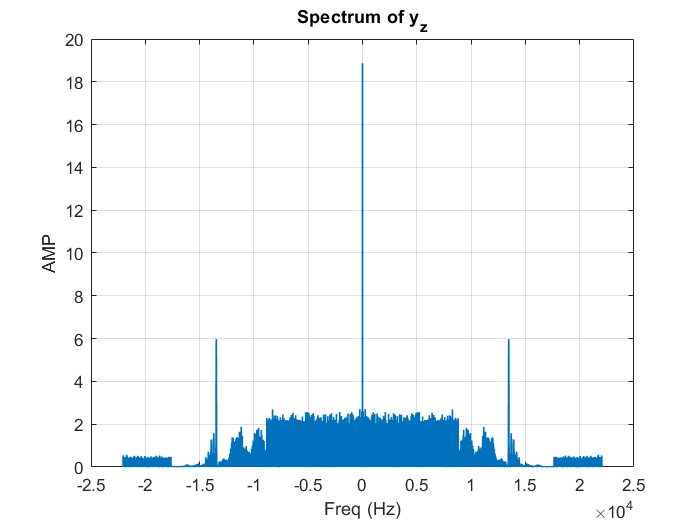

figure;
FFT(y_z, fs_z); title('Spectrum of y_z');

## Spectrum of the decoded audio(real audio)

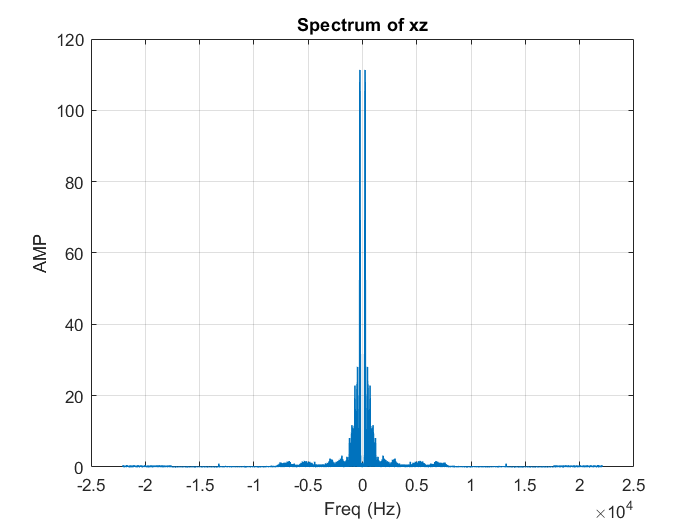


figure;
FFT(xz, fs_z); title('Spectrum of xz');

function Z = FFT(m, fs)
    M = fftshift(fft(m));
    N = numel(m);
    freq = (-N/2:N/2-1)/N*fs;
    plot(freq, abs(M), 'LineWidth', 1);
    grid on;
    ylabel('AMP');
    xlabel('Freq (Hz)');
end
